%postion

Write the loop closer equations here.

/*

*/

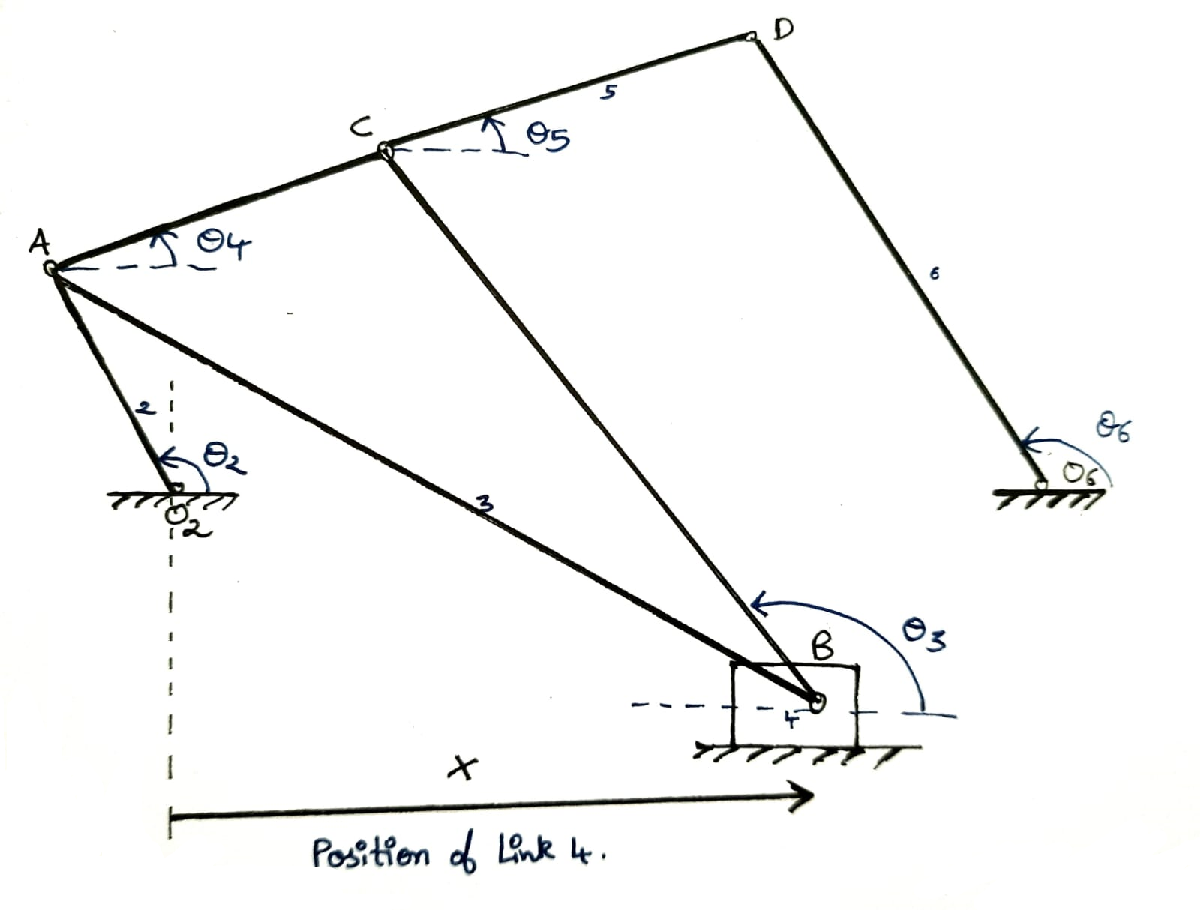

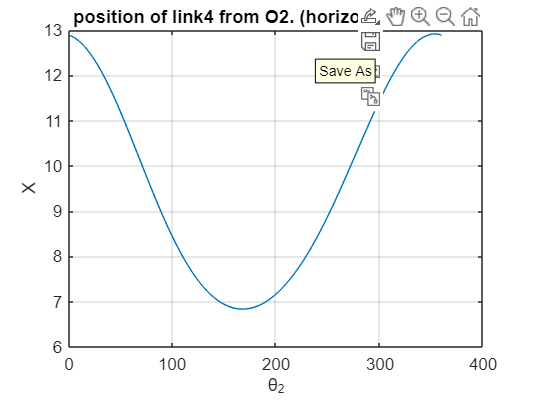

%This is main file to run all the functions related to finding angles.
%All the angles are stored in a combined matrix T.

%last edit 12:48 30/11

O2A=3;AC=4; AB=10; CB=8; CD=4; DO6=6; O2B=1.5;O2O6=8;
%O2A varies between 2-4 in
% t is theta.
% all angles are in radians unless mentioned.

L=[O2A AC AB CB CD DO6 O2B O2O6]; 
%all the lengths in mechanism
T=[];                 
tB=22.3316450092*pi/180; %Angle at ABC in triangle (i.e angle at B)
%all the angles in mechanism
t2=linspace(0,2*pi,361);
T=[t2];



%**********************************
%/********Finding ANGLES**********\%
%**********************************
T1=solve_for_t3_t4(L,T); %T1=[t3;t4];
T=[T;T1];
%T=[t2;t3;t4] in radians.

T2=solve_for_t5_t6(L,T,[1;1]); %T2=[t5;t6]
T=[T;T2];
%T=[t2;t3;t4;t5;t6] in radians.

%********plots**********
x=O2A.*cos(T(1,:))-AB.*cos(T(2,:)+tB);
figure
plot(T(1,:)*180/pi,x)
xlabel('\theta_2')
ylabel('X')
title('position of link4 from O2. (horizontal distance)')
grid on

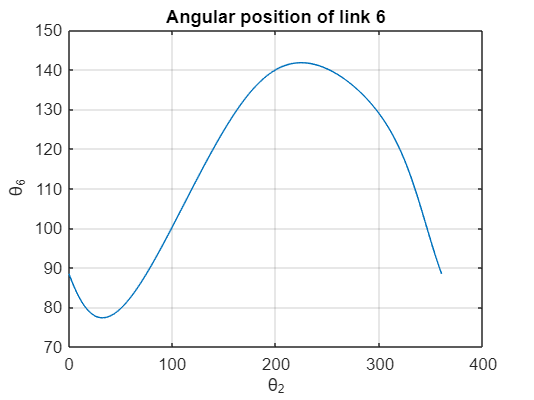


figure 
plot(T(1,:)*180/pi,T2(2,:)*180/pi)
xlabel('\theta_2')
ylabel('\theta_6')
title('Angular position of link 6')
grid on

clearvars -except T L tB
